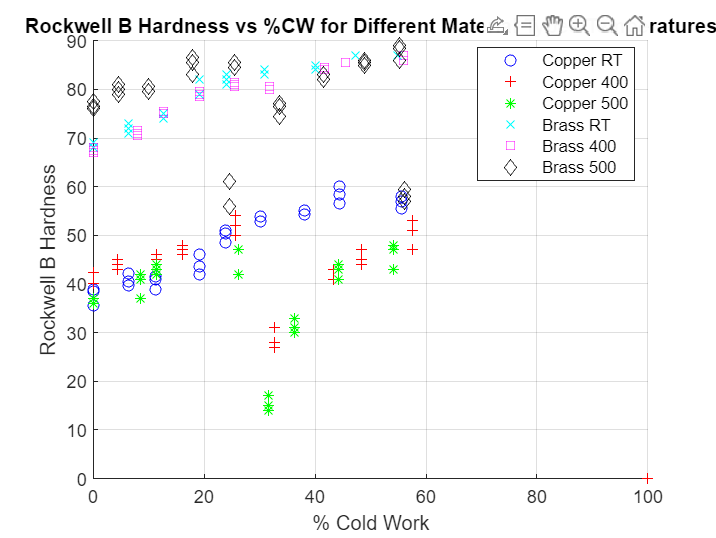

% This algorithm plots % Cold Work and Rockwell B Hardness for various materials at certain
% temperatures based on a .csv file 
% NOTE: I modified the original spreadsheet data so that the .csv file would be easier
% to plot in MATLAB, the modified .csv can be found on my github: 
% ATTRIBUTION: algorithm was troubleshooted with the help of ChatGPT and MathWorks.com, but initially
% coded and attempted by myself (Vinay Rao)

% Load the CSV file
filename = '/Users/vinay/Downloads/Lab7DataRearranged.csv'; % Update with the correct path to your CSV file
data = readtable(filename);

% Initialize the figure
figure;
hold on;

% Define material types, colors, and markers for plotting
material_types = {'Copper RT', 'Copper 400', 'Copper 500', 'Brass RT', 'Brass 400', 'Brass 500'};
colors = {'b', 'r', 'g', 'c', 'm', 'k'}; % Assign a color for each xmaterial type
markers = {'o', '+', '*', 'x', 's', 'd', '^', 'v', '>', '<', 'p', 'h'};

% Loop through each material type and plot the data
for i = 1:length(material_types)
    % Filter data for the current material type
    type_data = data(strcmp(data.Material, material_types{i}), :);
    % Create a scatter plot for the current material type
    scatter(type_data.CW, type_data.HRB, 'DisplayName', material_types{i}, 'MarkerEdgeColor', colors{i},'Marker', markers{mod(i-1, length(markers)) + 1});
end

% Customize the plot
xlabel('% Cold Work');
ylabel('Rockwell B Hardness');
title('Rockwell B Hardness vs %CW for Different Material Types/Temperatures');
legend('Location', 'best');
grid on; % Add grid for better readability
hold off; % Release the figure for further commands